# ME 535 Assignment 2, Fall 2018

# Debabrata Auddya

## **Exercise 3.1 - **Bernstein polynomials

**Question a. **

**Ans: Degree Four Bernstein polynomials are plotted. **

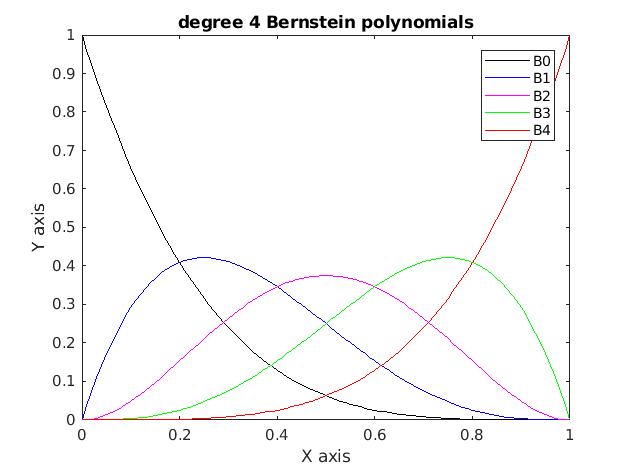

clear all
close all 
figure(1); cla;
colorstring = 'kbmgr';
u = 0:0.01:1;
for i = 0:4
    b = (factorial(4)/(factorial(i)*factorial(4 - i))* (u.^i).*((1-u).^(4 - i)));
    plot(u,b,  colorstring(i+1))
    xlabel("X axis")
    ylabel("Y axis")
    hold on
end 
legend("B0","B1","B2","B3","B4");
title("degree 4 Bernstein polynomials")
hold off

**Question b. : Maximum and Minimum values of the polynomials**

clear all
u = 0.5;
c = 0;
for i = 0:4
    b = (factorial(4)/(factorial(i)*factorial(4 - i))* (0.5^i).*((1-0.5).^(4 - i)));
    X = sprintf('The value of polynomial B%d at u=0.5 is %d',i,b);
    disp(X)
    c = c+b;
end 

The value of polynomial B0 at u=0.5 is 6.250000e-02
The value of polynomial B1 at u=0.5 is 2.500000e-01
The value of polynomial B2 at u=0.5 is 3.750000e-01
The value of polynomial B3 at u=0.5 is 2.500000e-01
The value of polynomial B4 at u=0.5 is 6.250000e-02


**Question c. : Sum of polynomials**

Y = sprintf('Sum of polynomial is %d',c);
disp(Y)

Sum of polynomial is 1


**Question d. : Position where these polynomials obtain maximum value**

clear all
clc
figure(1); cla;
colorstring = 'kbmgr';
u = 0:0.01:1;
for i = 0:4
    b = (factorial(4)/(factorial(i)*factorial(4 - i))* (u.^i).*((1-u).^(4 - i)));
    plot(u,b,'Color',colorstring(i+1))
    hold on
    xlabel("X axis")
    ylabel("Y axis")
    maxb = max(b);  % Find max value over all elements.
    bmax=max(b);
    xmax=u(find(b == bmax));
    Z = sprintf('Maximum value of polynomial B%d is %d at x=%d',i,max(b),xmax);
    disp(Z)
    plot(xmax,max(b),'o','MarkerSize',10)
    X = sprintf('The maximum value of polynomial B%d is %d',i,max(b));
    disp(X)
    Y = sprintf('The minimum value of polynomial B%d is %d',i,min(b));
    disp(Y)
end 

Maximum value of polynomial B0 is 1 at x=0


The maximum value of polynomial B0 is 1


The minimum value of polynomial B0 is 0


Maximum value of polynomial B1 is 4.218750e-01 at x=2.500000e-01


The maximum value of polynomial B1 is 4.218750e-01


The minimum value of polynomial B1 is 0


Maximum value of polynomial B2 is 3.750000e-01 at x=5.000000e-01


The maximum value of polynomial B2 is 3.750000e-01


The minimum value of polynomial B2 is 0


Maximum value of polynomial B3 is 4.218750e-01 at x=7.500000e-01


The maximum value of polynomial B3 is 4.218750e-01


The minimum value of polynomial B3 is 0


Maximum value of polynomial B4 is 1 at x=1


The maximum value of polynomial B4 is 1


The minimum value of polynomial B4 is 0


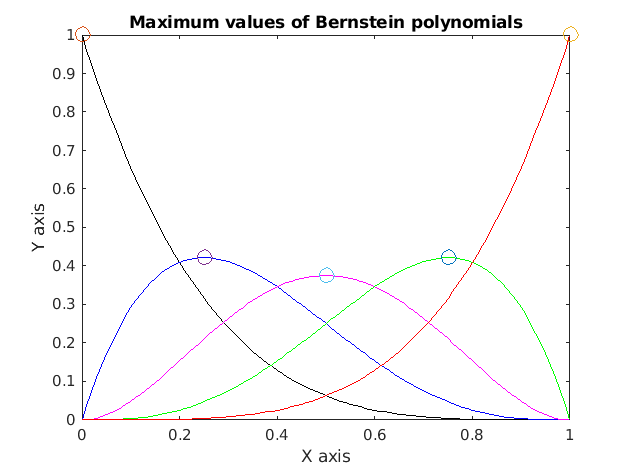

%legend("B0","B1","B2","B3","B4");
title("Maximum values of Bernstein polynomials")
hold off

**Question d. Part 2 Mathematical proof where Bernstein Polynomials takes maximum value**


$$\text{The Bernstein polynomial has a general expression}\\
B_{i,d} = \frac{d!}{i!(d-i)!} (i-u)^{d-i}u^{i} \\
\text{Taking a derivative with respect to u}\\
B_{i,d}^{'} = \frac{d!}{i!(d-i)!}( (d-i)(1-u)^{d-i-1}u^i(-1) + iu^{i-1}(1-u)^{d-i} )\\
\text{Setting the above expression to zero}\\
(1 - u)^{d-i-1}u^{i - 1}((i-d)u + i(1 - u)) = 0\\
\text{Therefore, simplifying gives}\\
i = ud\\
u = i/d\\
\text{So for the Bernstein polynomials, the maximum values are}\\
B_{0,4} = 0/4 = 0\\
B_{1,4} = 1/4 = 0.25\\
B_{2,4} = 2/4 = 0.5\\
B_{3,4} = 3/4 = 0.75\\
B_{4,4} = 4/4 = 1\\
$$


## Exercise 3.2 - Bezier curve through Bernstein polynomials

clear all
u = [0.2 0.5 0.8];
for i=1:size(u,2)
    c = (1 - u(i))^4.*[0 ; 0] + 4*(1 - u(i))^3.*u(i).*[1;2] + 6*(1 - u(i))^2.*u(i)^2.*[3 ; 5] + 4*(1 - u(i)).*u(i)^3.*[4 ; 4] + u(i)^4.*[5 ; 0];
    X = sprintf('Value of Bezier curve at u=%d is %d and %d',u(i),c(1,:),c(2,:));
    disp(X)
end 

Value of Bezier curve at u=2.000000e-01 is 9.808000e-01 and 1.689600e+00
Value of Bezier curve at u=5.000000e-01 is 2.687500e+00 and 3.375000e+00
Value of Bezier curve at u=8.000000e-01 is 4.172800e+00 and 2.457600e+00


## Exercise 3.4 - deCasteljau Algorithm 

**Question a,b: Compute curve points using above algorithm**

clear all
close all
u =[0.2 0.5 0.8];
d = 4; %degree of the polynomial
c = size(u,2);
for j=1:c
P =[0,0; 1,2; 3,5; 4,4; 5,0];
  for r=1:d
    for i=1:(d+1-r) % the array index in Matlab starts with 1, not 0.
        P(i,:) = (1-u(j))*P(i,:) + u(j)*P(i+1,:);
    end
  end
  fprintf('Value of Bezier curve point using deCasteljau algorithm at u=%d is given as %i,%i \n',u(j),P(1,:))
end 

Value of Bezier curve point using deCasteljau algorithm at u=2.000000e-01 is given as 9.808000e-01,1.689600e+00 
Value of Bezier curve point using deCasteljau algorithm at u=5.000000e-01 is given as 2.687500e+00,3.375000e+00 
Value of Bezier curve point using deCasteljau algorithm at u=8.000000e-01 is given as 4.172800e+00,2.457600e+00 


**Question c: Compare results with 3.3**

The results using deCasteljau algorithm and Bernstein polynomials are the same. 

**Question d: Adding one control point (0,0), closed curve, no g1 continuity**

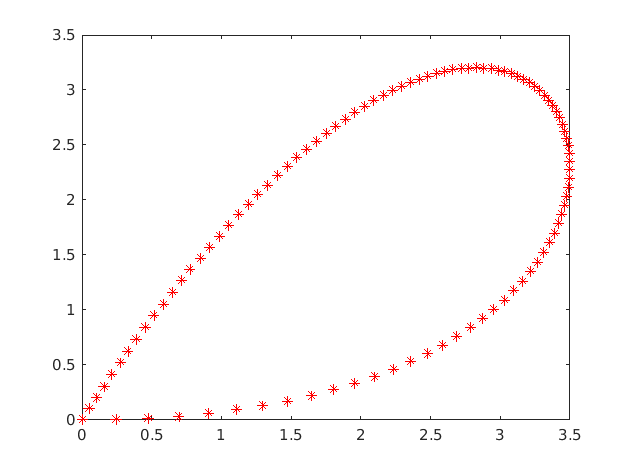

%adding [0,0] at the end or [5,0] at the beginning closes the curve
%In this example [0,0] has been used to close the curve 
clear all 
clc
u = 0:0.01:1;
for i=1:size(u,2)
    c = (1 - u(i))^5.*[0 ; 0] + 5*(1 - u(i))^4.*u(i).*[1;2] + 10*(1 - u(i))^3.*u(i)^2.*[3 ; 5] + 10*(1 - u(i))^2.*u(i)^3.*[4 ; 4] + 5*(1 - u(i))*u(i)^4.*[5 ; 0] + u(i)^5.*[0 ; 0];
    %X = sprintf('Value of Bezier curve at u=%d is %d and %d',u(i),c(1,:),c(2,:));
    plot(c(1,:),c(2,:),'-*r')
    hold on
end 

**Question e: Adding two control points, (2.5,0) at the beginning and the end ensuring c1 and g1 continuity **

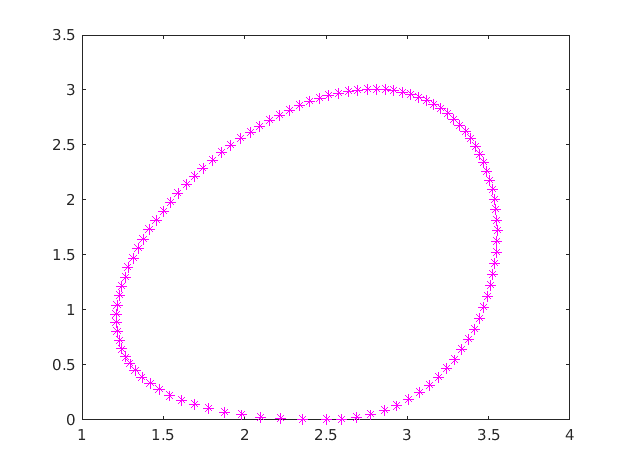

%adding [2.5,0] at the beginning and [2.5,0] at the ended smoothens the curve
%and ensures C1 and G1 continuity
%In this example [0,0] has been used to close the curve 
clear all
figure(2);
clc
u = 0:0.01:1;
for i=1:size(u,2)
    c = (1 - u(i))^6.*[2.5 ; 0] + 6*(1 - u(i))^5.*u(i).*[0;0] + 15*(1 - u(i))^4.*u(i)^2.*[1;2] + 20*(1 - u(i))^3.*u(i)^3.*[3 ; 5] + 15*(1 - u(i))^2.*u(i)^4.*[4 ; 4] + 5*(1 - u(i))*u(i)^5.*[5 ; 0] + u(i)^6.*[2.5 ; 0];
    %X = sprintf('Value of Bezier curve at u=%d is %d and %d',u(i),c(1,:),c(2,:));
    plot(c(1,:),c(2,:),'-*m')
    hold on
end 

**Question No 3.5 - Shear Transformation of curves**

**a. Modelling Initials **

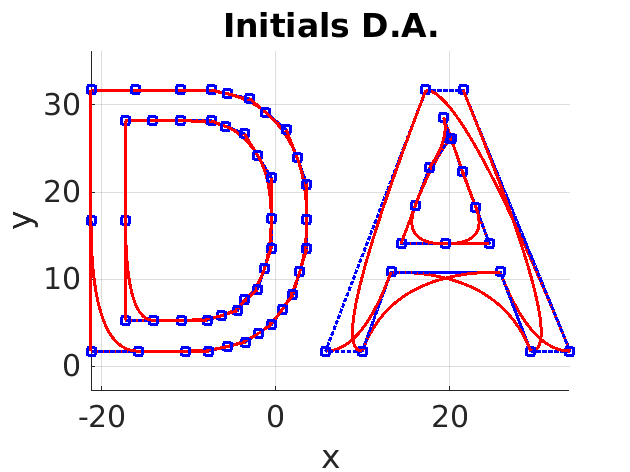

% This program draws the alphabets of the initials defined in quadratic or linear Bezier
% curves.
% It applies an affine transformation on the letter.
clear all;
n = 50;  % number of point on each Bezier curve

styleP = ':bs';
styleQ = 'r'; %'-b'
stylenP = ':bs';
stylenQ = 'r';

DrawOldLetter = true;
DrawNewLetter = true;

h = figure(3);
hold on;

% control points for contour 1
% Outer D
P1 = [-21.210, 31.722, 0
    -16.046, 31.722, 0
    -10.882, 31.722, 0];
P2 = [-16.046, 31.722, 0
    -10.882, 31.722, 0
    -7.385, 31.722, 0];
P3 = [-10.882, 31.722, 0
    -7.385, 31.722, 0
    -5.545, 31.292,0];
P4 = [-7.385, 31.722, 0
    -5.545, 31.292, 0
    -2.968, 30.699, 0];
P5 = [-5.545, 31.292, 0
    -2.968, 30.699, 0
    -1.148, 29.145, 0];
P6 = [-2.968, 30.699, 0
    -1.148, 29.145, 0
    1.224, 27.141, 0];
P7 = [-1.148, 29.145, 0
    1.224, 27.141, 0
    2.458, 23.974, 0];
P8 = [1.224, 27.141, 0
    2.458, 23.974, 0
    3.576, 20.904, 0];
P9 = [2.458, 23.974, 0
    3.576, 20.904, 0
    3.576, 16.895, 0];
P10 = [3.576, 20.904, 0
    3.576, 16.895, 0
    3.576, 13.480, 0];
P11 = [3.576, 16.895, 0
    3.576, 13.480, 0
    2.787, 10.931, 0];
P12 = [3.576, 13.480, 0
    2.787, 10.931, 0
    1.981, 8.204, 0];
P13 = [2.787, 10.931, 0
    1.981, 8.204, 0
    0.733, 6.476, 0];
P14 = [1.981, 8.204, 0
    0.733, 6.476, 0
    -0.514, 4.748, 0];
P15 = [0.733, 6.476, 0
    -0.514, 4.748, 0
    -1.997, 3.756, 0];
P16 = [-0.514, 4.748, 0
    -1.997, 3.756, 0
    -3.480, 2.765, 0];
P17 = [-1.997, 3.756, 0
    -3.480, 2.765, 0
    -5.576, 2.253, 0];
P18 = [-3.480, 2.765, 0
    -5.576, 2.253, 0
    -7.672, 1.742, 0];
P19 = [-5.576, 2.253, 0
    -7.672, 1.742, 0
    -10.392, 1.742, 0];
P20 = [-7.672, 1.742, 0
    -10.392, 1.742, 0
    -15.801, 1.742, 0];
P21 = [-10.392, 1.742, 0
    -15.801, 1.742, 0
    -21.210, 1.742, 0];
P22 = [-15.801, 1.742, 0
    -21.210, 1.742, 0
    -21.210, 16.732, 0];
P23 = [-21.210, 1.742, 0
    -21.210, 16.732, 0
    -21.210, 31.722,0];
    
    
% control points for contour 2
% Inner ring of D 

B1 = [-17.242, 28.184, 0
    -14.093, 28.184, 0
    -10.944, 28.184, 0];
B2 = [-14.093, 28.184, 0
    -10.944, 28.184, 0
    -7.406, 28.184, 0];
B3 = [-10.944, 28.184, 0
    -7.406, 28.184, 0
    -5.811, 27.570, 0];
B4 = [-7.406, 28.184, 0
    -5.811, 27.570, 0
    -3.602, 26.711, 0];
B5 = [-5.811, 27.570, 0
    -3.602, 26.711, 0
    -2.058, 24.186, 0];
B6 = [-3.602, 26.711, 0
    -2.058, 24.186, 0
    -0.514, 21.660, 0];
B7 = [-2.058, 24.186, 0
    -0.514, 21.660, 0
    -0.514, 16.957, 0];
B8 = [-0.514, 21.660, 0
    -0.514, 16.957, 0
    -0.514, 13.562, 0];
B9 = [-0.514, 16.957, 0
    -0.514, 13.562, 0
    -1.302, 11.180, 0];
B10 = [ -0.514, 13.562, 0
    -1.302, 11.180, 0
    -2.089, 8.797, 0];
B11 = [-1.302, 11.180, 0
    -2.089, 8.797, 0
    -3.567, 7.614, 0];
B12 = [-2.089, 8.797, 0
    -3.567, 7.614, 0
    -4.392, 6.377, 0];
B13 = [-3.567, 7.614, 0
    -4.392, 6.377, 0
    -6.189, 5.832, 0];
B14 = [-4.392, 6.377, 0
    -6.189, 5.832, 0
    -7.876, 5.280, 0];
B15 = [-6.189, 5.832, 0
    -7.876, 5.280, 0
    -10.841, 5.280, 0];
B16 = [-7.876, 5.280, 0
    -10.841, 5.280, 0
    -14.042, 5.280, 0];
B17 = [-10.841, 5.280, 0
    -14.042, 5.280, 0
    -17.242, 5.280, 0];
B18 = [-14.042, 5.280, 0
    -17.242, 5.280, 0
    -17.242, 16.732, 0];
B19 = [-17.242, 5.280, 0
    -17.242, 16.732, 0
    -17.242, 28.184, 0];

%contour points for contour 3
%Outer ring of A

M1 = [17.252, 31.722, 0
    21.531, 31.722, 0
    33.801, 1.742, 0];
M2 = [21.531, 31.722, 0
    33.801, 1.742, 0
    29.281, 1.742, 0];
M3 = [33.801, 1.742, 0
    29.281, 1.742, 0
    25.784, 10.822, 0];
M4 = [29.281, 1.742, 0
    25.784, 10.822, 0
    13.248, 10.822, 0];
M5 = [25.784, 10.822, 0
    13.248, 10.822, 0
    9.956, 1.742, 0];
M6 = [13.248, 10.822, 0
    9.956, 1.742, 0
    5.743 1.742, 0];
M7 = [9.956, 1.742, 0
    5.743 1.742, 0
    17.257, 31.722 0];

%contour points for contour 4
%Inner ring of B

N1 = [19.302, 28.572, 0
    20.153, 26.177, 0
    21.428, 22.356, 0];
N2 = [20.153, 26.177, 0
    21.428, 22.356, 0
    22.993, 18.264, 0];
N3 = [ 21.428, 22.356, 0
    22.993, 18.264, 0
    24.557, 14.053, 0];
N4 = [22.993, 18.264, 0
    24.557, 14.053, 0
    19.475, 14.053, 0];
N5 = [24.557, 14.053, 0
    19.475, 14.053, 0
    14.394, 14.053, 0];
N6 = [19.475, 14.053, 0
    14.394, 14.053, 0
    16.040, 18.450, 0];
N7 = [14.394, 14.053, 0
    16.040, 18.450, 0
    17.686, 22.846, 0];
N8 = [16.040, 18.450, 0
    17.686, 22.846, 0
    19.997, 26.139, 0];
N9 = [17.686, 22.846, 0
    19.997, 26.139, 0
    19.302, 28.572, 0];

if DrawOldLetter==true
    Q = bezierCurve(P1, n); bezierCurvePlot(P1, Q, styleP, styleQ); 
    Q = bezierCurve(P2, n); bezierCurvePlot(P2, Q, styleP, styleQ);
    Q = bezierCurve(P3, n); bezierCurvePlot(P3, Q, styleP, styleQ);
    Q = bezierCurve(P4, n); bezierCurvePlot(P4, Q, styleP, styleQ);
    Q = bezierCurve(P5, n); bezierCurvePlot(P5, Q, styleP, styleQ); 
    Q = bezierCurve(P6, n); bezierCurvePlot(P6, Q, styleP, styleQ);
    Q = bezierCurve(P7, n); bezierCurvePlot(P7, Q, styleP, styleQ);
    Q = bezierCurve(P8, n); bezierCurvePlot(P8, Q, styleP, styleQ);
    Q = bezierCurve(P9, n); bezierCurvePlot(P9, Q, styleP, styleQ);
    Q = bezierCurve(P10, n); bezierCurvePlot(P10, Q, styleP, styleQ);
    Q = bezierCurve(P11, n); bezierCurvePlot(P11, Q, styleP, styleQ);
    Q = bezierCurve(P12, n); bezierCurvePlot(P12, Q, styleP, styleQ);
    Q = bezierCurve(P13, n); bezierCurvePlot(P13, Q, styleP, styleQ);
    Q = bezierCurve(P14, n); bezierCurvePlot(P14, Q, styleP, styleQ);
    Q = bezierCurve(P15, n); bezierCurvePlot(P15, Q, styleP, styleQ);
    Q = bezierCurve(P16, n); bezierCurvePlot(P16, Q, styleP, styleQ);
    Q = bezierCurve(P17, n); bezierCurvePlot(P17, Q, styleP, styleQ);
    Q = bezierCurve(P18, n); bezierCurvePlot(P18, Q, styleP, styleQ);
    Q = bezierCurve(P19, n); bezierCurvePlot(P19, Q, styleP, styleQ);
    Q = bezierCurve(P20, n); bezierCurvePlot(P20, Q, styleP, styleQ);
    Q = bezierCurve(P21, n); bezierCurvePlot(P21, Q, styleP, styleQ);
    Q = bezierCurve(P22, n); bezierCurvePlot(P22, Q, styleP, styleQ);
    Q = bezierCurve(P23, n); bezierCurvePlot(P23, Q, styleP, styleQ);

    Q = bezierCurve(M1, n); bezierCurvePlot(M1, Q, styleP, styleQ); 
    Q = bezierCurve(M2, n); bezierCurvePlot(M2, Q, styleP, styleQ);
    Q = bezierCurve(M3, n); bezierCurvePlot(M3, Q, styleP, styleQ);
    Q = bezierCurve(M4, n); bezierCurvePlot(M4, Q, styleP, styleQ);
    Q = bezierCurve(M5, n); bezierCurvePlot(M5, Q, styleP, styleQ); 
    Q = bezierCurve(M6, n); bezierCurvePlot(M6, Q, styleP, styleQ);
    Q = bezierCurve(M7, n); bezierCurvePlot(M7, Q, styleP, styleQ);
    
    Q = bezierCurve(N1, n); bezierCurvePlot(N1, Q, styleP, styleQ);  
    Q = bezierCurve(N2, n); bezierCurvePlot(N2, Q, styleP, styleQ);
    Q = bezierCurve(N3, n); bezierCurvePlot(N3, Q, styleP, styleQ);
    Q = bezierCurve(N4, n); bezierCurvePlot(N4, Q, styleP, styleQ);
    Q = bezierCurve(N5, n); bezierCurvePlot(N5, Q, styleP, styleQ); 
    Q = bezierCurve(N6, n); bezierCurvePlot(N6, Q, styleP, styleQ);
    Q = bezierCurve(N7, n); bezierCurvePlot(N7, Q, styleP, styleQ);
    Q = bezierCurve(N8, n); bezierCurvePlot(N8, Q, styleP, styleQ);
    Q = bezierCurve(N9, n); bezierCurvePlot(N9, Q, styleP, styleQ);
    
    Q = bezierCurve(B1, n); bezierCurvePlot(B1, Q, styleP, styleQ); 
    Q = bezierCurve(B2, n); bezierCurvePlot(B2, Q, styleP, styleQ);
    Q = bezierCurve(B3, n); bezierCurvePlot(B3, Q, styleP, styleQ);
    Q = bezierCurve(B4, n); bezierCurvePlot(B4, Q, styleP, styleQ);
    Q = bezierCurve(B5, n); bezierCurvePlot(B5, Q, styleP, styleQ); 
    Q = bezierCurve(B6, n); bezierCurvePlot(B6, Q, styleP, styleQ);
    Q = bezierCurve(B7, n); bezierCurvePlot(B7, Q, styleP, styleQ);
    Q = bezierCurve(B8, n); bezierCurvePlot(B8, Q, styleP, styleQ);
    Q = bezierCurve(B9, n); bezierCurvePlot(B9, Q, styleP, styleQ);
    Q = bezierCurve(B10, n); bezierCurvePlot(B10, Q, styleP, styleQ); 
    Q = bezierCurve(B11, n); bezierCurvePlot(B11, Q, styleP, styleQ); 
    Q = bezierCurve(B12, n); bezierCurvePlot(B12, Q, styleP, styleQ);
    Q = bezierCurve(B13, n); bezierCurvePlot(B13, Q, styleP, styleQ);
    Q = bezierCurve(B14, n); bezierCurvePlot(B14, Q, styleP, styleQ);
    Q = bezierCurve(B15, n); bezierCurvePlot(B15, Q, styleP, styleQ); 
    Q = bezierCurve(B16, n); bezierCurvePlot(B16, Q, styleP, styleQ);
    Q = bezierCurve(B17, n); bezierCurvePlot(B17, Q, styleP, styleQ);
    Q = bezierCurve(B18, n); bezierCurvePlot(B18, Q, styleP, styleQ);
    Q = bezierCurve(B19, n); bezierCurvePlot(B19, Q, styleP, styleQ);
   
end

set(gca,'FontSize',20)    
title('Initials D.A.');
xlabel('x','FontSize',20);
ylabel('y','FontSize',20);
zlabel('z','FontSize',20);

grid on;
axis equal
axis on

**b. The value of a and b is 1 and 0 respectively **

**    after solving the equation **

   
$$\left\lbrack \begin{array}{cccc}
0 & 1 & 2 & 1\\
0 & 0 & 1 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\text{ } & a\\
b & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
0 & 1 & 1 & 0\\
0 & 0 & 1 & 1
\end{array}\right\rbrack$$


    Thus the shear transformation matrix looks like:

   
$$\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


**c. The Shear Transformation of the Initials makes it: **

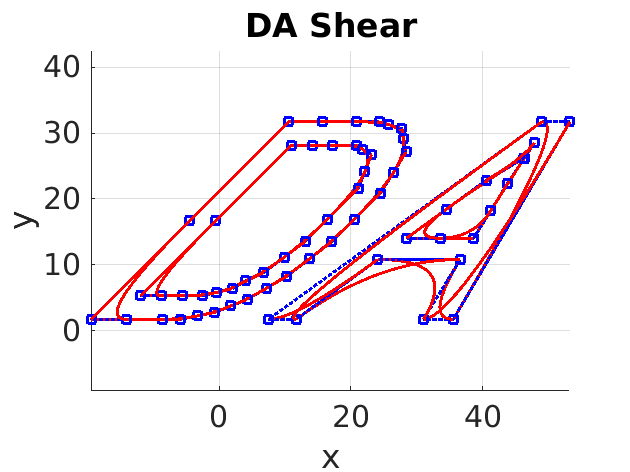

% This program draws the letter "DA" defined in quadratic or linear Bezier
% curves.
% It applies an affine transformation on the letter.

clear all;
n = 50;  % number of point on each Bezier curve

styleP = ':bs';
styleQ = 'r'; %'-b'
stylenP = ':bs';
stylenQ = 'r';

DrawOldLetter = true;
DrawNewLetter = true;

h = figure;
hold on;

% control points for contour 1
% Outer D
P1 = [-21.210, 31.722, 0
    -16.046, 31.722, 0
    -10.882, 31.722, 0];
P2 = [-16.046, 31.722, 0
    -10.882, 31.722, 0
    -7.385, 31.722, 0];
P3 = [-10.882, 31.722, 0
    -7.385, 31.722, 0
    -5.545, 31.292,0];
P4 = [-7.385, 31.722, 0
    -5.545, 31.292, 0
    -2.968, 30.699, 0];
P5 = [-5.545, 31.292, 0
    -2.968, 30.699, 0
    -1.148, 29.145, 0];
P6 = [-2.968, 30.699, 0
    -1.148, 29.145, 0
    1.224, 27.141, 0];
P7 = [-1.148, 29.145, 0
    1.224, 27.141, 0
    2.458, 23.974, 0];
P8 = [1.224, 27.141, 0
    2.458, 23.974, 0
    3.576, 20.904, 0];
P9 = [2.458, 23.974, 0
    3.576, 20.904, 0
    3.576, 16.895, 0];
P10 = [3.576, 20.904, 0
    3.576, 16.895, 0
    3.576, 13.480, 0];
P11 = [3.576, 16.895, 0
    3.576, 13.480, 0
    2.787, 10.931, 0];
P12 = [3.576, 13.480, 0
    2.787, 10.931, 0
    1.981, 8.204, 0];
P13 = [2.787, 10.931, 0
    1.981, 8.204, 0
    0.733, 6.476, 0];
P14 = [1.981, 8.204, 0
    0.733, 6.476, 0
    -0.514, 4.748, 0];
P15 = [0.733, 6.476, 0
    -0.514, 4.748, 0
    -1.997, 3.756, 0];
P16 = [-0.514, 4.748, 0
    -1.997, 3.756, 0
    -3.480, 2.765, 0];
P17 = [-1.997, 3.756, 0
    -3.480, 2.765, 0
    -5.576, 2.253, 0];
P18 = [-3.480, 2.765, 0
    -5.576, 2.253, 0
    -7.672, 1.742, 0];
P19 = [-5.576, 2.253, 0
    -7.672, 1.742, 0
    -10.392, 1.742, 0];
P20 = [-7.672, 1.742, 0
    -10.392, 1.742, 0
    -15.801, 1.742, 0];
P21 = [-10.392, 1.742, 0
    -15.801, 1.742, 0
    -21.210, 1.742, 0];
P22 = [-15.801, 1.742, 0
    -21.210, 1.742, 0
    -21.210, 16.732, 0];
P23 = [-21.210, 1.742, 0
    -21.210, 16.732, 0
    -21.210, 31.722,0];
    
    
% control points for contour 2
% Inner ring of D 

B1 = [-17.242, 28.184, 0
    -14.093, 28.184, 0
    -10.944, 28.184, 0];
B2 = [-14.093, 28.184, 0
    -10.944, 28.184, 0
    -7.406, 28.184, 0];
B3 = [-10.944, 28.184, 0
    -7.406, 28.184, 0
    -5.811, 27.570, 0];
B4 = [-7.406, 28.184, 0
    -5.811, 27.570, 0
    -3.602, 26.711, 0];
B5 = [-5.811, 27.570, 0
    -3.602, 26.711, 0
    -2.058, 24.186, 0];
B6 = [-3.602, 26.711, 0
    -2.058, 24.186, 0
    -0.514, 21.660, 0];
B7 = [-2.058, 24.186, 0
    -0.514, 21.660, 0
    -0.514, 16.957, 0];
B8 = [-0.514, 21.660, 0
    -0.514, 16.957, 0
    -0.514, 13.562, 0];
B9 = [-0.514, 16.957, 0
    -0.514, 13.562, 0
    -1.302, 11.180, 0];
B10 = [ -0.514, 13.562, 0
    -1.302, 11.180, 0
    -2.089, 8.797, 0];
B11 = [-1.302, 11.180, 0
    -2.089, 8.797, 0
    -3.567, 7.614, 0];
B12 = [-2.089, 8.797, 0
    -3.567, 7.614, 0
    -4.392, 6.377, 0];
B13 = [-3.567, 7.614, 0
    -4.392, 6.377, 0
    -6.189, 5.832, 0];
B14 = [-4.392, 6.377, 0
    -6.189, 5.832, 0
    -7.876, 5.280, 0];
B15 = [-6.189, 5.832, 0
    -7.876, 5.280, 0
    -10.841, 5.280, 0];
B16 = [-7.876, 5.280, 0
    -10.841, 5.280, 0
    -14.042, 5.280, 0];
B17 = [-10.841, 5.280, 0
    -14.042, 5.280, 0
    -17.242, 5.280, 0];
B18 = [-14.042, 5.280, 0
    -17.242, 5.280, 0
    -17.242, 16.732, 0];
B19 = [-17.242, 5.280, 0
    -17.242, 16.732, 0
    -17.242, 28.184, 0];

%contour points for contour 3
%Outer ring of A

M1 = [17.252, 31.722, 0
    21.531, 31.722, 0
    33.801, 1.742, 0];
M2 = [21.531, 31.722, 0
    33.801, 1.742, 0
    29.281, 1.742, 0];
M3 = [33.801, 1.742, 0
    29.281, 1.742, 0
    25.784, 10.822, 0];
M4 = [29.281, 1.742, 0
    25.784, 10.822, 0
    13.248, 10.822, 0];
M5 = [25.784, 10.822, 0
    13.248, 10.822, 0
    9.956, 1.742, 0];
M6 = [13.248, 10.822, 0
    9.956, 1.742, 0
    5.743 1.742, 0];
M7 = [9.956, 1.742, 0
    5.743 1.742, 0
    17.257, 31.722 0];

%contour points for contour 4
%Inner ring of B

N1 = [19.302, 28.572, 0
    20.153, 26.177, 0
    21.428, 22.356, 0];
N2 = [20.153, 26.177, 0
    21.428, 22.356, 0
    22.993, 18.264, 0];
N3 = [ 21.428, 22.356, 0
    22.993, 18.264, 0
    24.557, 14.053, 0];
N4 = [22.993, 18.264, 0
    24.557, 14.053, 0
    19.475, 14.053, 0];
N5 = [24.557, 14.053, 0
    19.475, 14.053, 0
    14.394, 14.053, 0];
N6 = [19.475, 14.053, 0
    14.394, 14.053, 0
    16.040, 18.450, 0];
N7 = [14.394, 14.053, 0
    16.040, 18.450, 0
    17.686, 22.846, 0];
N8 = [16.040, 18.450, 0
    17.686, 22.846, 0
    19.997, 26.139, 0];
N9 = [17.686, 22.846, 0
    19.997, 26.139, 0
    19.302, 28.572, 0];

%shear transformation
T = [1 1 0
     0 1 0
     0 0 0];
nP1 = P1*T';
nP2 = P2*T';
nP3 = P3*T';
nP4 = P4*T';
nP5 = P5*T';
nP6 = P6*T';
nP7 = P7*T';
nP8 = P8*T';
nP9 = P9*T';
nP10 = P10*T';
nP11 = P11*T';
nP12 = P12*T';
nP13 = P13*T';
nP14 = P14*T';
nP15 = P15*T';
nP16 = P16*T';
nP17 = P17*T';
nP18 = P18*T';
nP19 = P19*T';
nP20 = P20*T';
nP21 = P21*T';
nP22 = P22*T';
nP23 = P23*T';


nM1 = M1*T';
nM2 = M2*T';
nM3 = M3*T';
nM4 = M4*T';
nM5 = M5*T';
nM6 = M6*T';
nM7 = M7*T';

nN1 = N1*T';
nN2 = N2*T';
nN3 = N3*T';
nN4 = N4*T';
nN5 = N5*T';
nN6 = N6*T';
nN7 = N7*T';
nN8 = N8*T';
nN9 = N9*T';

nB1 = B1*T';
nB2 = B2*T';
nB3 = B3*T';
nB4 = B4*T';
nB5 = B5*T';
nB6 = B6*T';
nB7 = B7*T';
nB8 = B8*T';
nB9 = B9*T';
nB10 = B10*T';
nB11 = B11*T';
nB12 = B12*T';
nB13 = B13*T';
nB14 = B14*T';
nB15 = B15*T';
nB16 = B16*T';
nB17 = B17*T';
nB18 = B18*T';
nB19 = B19*T';

if DrawNewLetter == true
    Q = bezierCurve(nP1, n); bezierCurvePlot(nP1, Q, stylenP, stylenQ); 
    Q = bezierCurve(nP2, n); bezierCurvePlot(nP2, Q, stylenP, stylenQ);
    Q = bezierCurve(nP3, n); bezierCurvePlot(nP3, Q, stylenP, stylenQ);
    Q = bezierCurve(nP4, n); bezierCurvePlot(nP4, Q, stylenP, stylenQ);
    Q = bezierCurve(nP5, n); bezierCurvePlot(nP5, Q, stylenP, stylenQ); 
    Q = bezierCurve(nP6, n); bezierCurvePlot(nP6, Q, stylenP, stylenQ);
    Q = bezierCurve(nP7, n); bezierCurvePlot(nP7, Q, stylenP, stylenQ);
    Q = bezierCurve(nP8, n); bezierCurvePlot(nP8, Q, stylenP, stylenQ);
    Q = bezierCurve(nP9, n); bezierCurvePlot(nP9, Q, stylenP, stylenQ);
    Q = bezierCurve(nP10, n); bezierCurvePlot(nP10, Q, stylenP, stylenQ);
    Q = bezierCurve(nP11, n); bezierCurvePlot(nP11, Q, stylenP, stylenQ);
    Q = bezierCurve(nP12, n); bezierCurvePlot(nP12, Q, stylenP, stylenQ);
    Q = bezierCurve(nP13, n); bezierCurvePlot(nP13, Q, stylenP, stylenQ);
    Q = bezierCurve(nP14, n); bezierCurvePlot(nP14, Q, stylenP, stylenQ);
    Q = bezierCurve(nP15, n); bezierCurvePlot(nP15, Q, stylenP, stylenQ); 
    Q = bezierCurve(nP16, n); bezierCurvePlot(nP16, Q, stylenP, stylenQ);
    Q = bezierCurve(nP17, n); bezierCurvePlot(nP17, Q, stylenP, stylenQ);
    Q = bezierCurve(nP18, n); bezierCurvePlot(nP18, Q, stylenP, stylenQ);
    Q = bezierCurve(nP19, n); bezierCurvePlot(nP19, Q, stylenP, stylenQ);
    Q = bezierCurve(nP20, n); bezierCurvePlot(nP20, Q, stylenP, stylenQ);
    Q = bezierCurve(nP21, n); bezierCurvePlot(nP21, Q, stylenP, stylenQ);
    Q = bezierCurve(nP22, n); bezierCurvePlot(nP22, Q, stylenP, stylenQ);
    Q = bezierCurve(nP23, n); bezierCurvePlot(nP23, Q, stylenP, stylenQ);
    
    
    Q = bezierCurve(nM1, n); bezierCurvePlot(nM1, Q, stylenP, stylenQ); 
    Q = bezierCurve(nM2, n); bezierCurvePlot(nM2, Q, stylenP, stylenQ);
    Q = bezierCurve(nM3, n); bezierCurvePlot(nM3, Q, stylenP, stylenQ);
    Q = bezierCurve(nM4, n); bezierCurvePlot(nM4, Q, stylenP, stylenQ);
    Q = bezierCurve(nM5, n); bezierCurvePlot(nM5, Q, stylenP, stylenQ); 
    Q = bezierCurve(nM6, n); bezierCurvePlot(nM6, Q, stylenP, stylenQ);
    Q = bezierCurve(nM7, n); bezierCurvePlot(nM7, Q, stylenP, stylenQ);
    
    Q = bezierCurve(nN1, n); bezierCurvePlot(nN1, Q, stylenP, stylenQ); 
    Q = bezierCurve(nN2, n); bezierCurvePlot(nN2, Q, stylenP, stylenQ);
    Q = bezierCurve(nN3, n); bezierCurvePlot(nN3, Q, stylenP, stylenQ);
    Q = bezierCurve(nN4, n); bezierCurvePlot(nN4, Q, stylenP, stylenQ);
    Q = bezierCurve(nN5, n); bezierCurvePlot(nN5, Q, stylenP, stylenQ); 
    Q = bezierCurve(nN6, n); bezierCurvePlot(nN6, Q, stylenP, stylenQ);
    Q = bezierCurve(nN7, n); bezierCurvePlot(nN7, Q, stylenP, stylenQ);
    Q = bezierCurve(nN8, n); bezierCurvePlot(nN8, Q, stylenP, stylenQ);
    Q = bezierCurve(nN9, n); bezierCurvePlot(nN9, Q, stylenP, stylenQ);


    Q = bezierCurve(nB1, n); bezierCurvePlot(nB1, Q, stylenP, stylenQ); 
    Q = bezierCurve(nB2, n); bezierCurvePlot(nB2, Q, stylenP, stylenQ);
    Q = bezierCurve(nB3, n); bezierCurvePlot(nB3, Q, stylenP, stylenQ);
    Q = bezierCurve(nB4, n); bezierCurvePlot(nB4, Q, stylenP, stylenQ);
    Q = bezierCurve(nB5, n); bezierCurvePlot(nB5, Q, stylenP, stylenQ); 
    Q = bezierCurve(nB6, n); bezierCurvePlot(nB6, Q, stylenP, stylenQ);
    Q = bezierCurve(nB7, n); bezierCurvePlot(nB7, Q, stylenP, stylenQ);
    Q = bezierCurve(nB8, n); bezierCurvePlot(nB8, Q, stylenP, stylenQ);
    Q = bezierCurve(nB9, n); bezierCurvePlot(nB9, Q, stylenP, stylenQ);
    Q = bezierCurve(nB10, n); bezierCurvePlot(nB10, Q, stylenP, stylenQ); 
    Q = bezierCurve(nB11, n); bezierCurvePlot(nB11, Q, stylenP, stylenQ); 
    Q = bezierCurve(nB12, n); bezierCurvePlot(nB12, Q, stylenP, stylenQ);
    Q = bezierCurve(nB13, n); bezierCurvePlot(nB13, Q, stylenP, stylenQ);
    Q = bezierCurve(nB14, n); bezierCurvePlot(nB14, Q, stylenP, stylenQ);
    Q = bezierCurve(nB15, n); bezierCurvePlot(nB15, Q, stylenP, stylenQ); 
    Q = bezierCurve(nB16, n); bezierCurvePlot(nB16, Q, stylenP, stylenQ);
    Q = bezierCurve(nB17, n); bezierCurvePlot(nB17, Q, stylenP, stylenQ);
    Q = bezierCurve(nB18, n); bezierCurvePlot(nB18, Q, stylenP, stylenQ);
    Q = bezierCurve(nB19, n); bezierCurvePlot(nB19, Q, stylenP, stylenQ);
     
end
    
set(gca,'FontSize',20)    
title('DA Shear');
xlabel('x','FontSize',20);
ylabel('y','FontSize',20);
zlabel('z','FontSize',20);

grid on;
axis equal
axis on